# **Koopman Operator: Benefits for Optimal Control**

**For linear systems, we know we can get an optimal feedback control through LQR. Through a toy problem, let us investigate how using a Koopman operator to rewrite the dynamics as a linear system**

## **Investigating the Dynamics**

We will define the dynamics as follows:


$$\pmatrix{\dot{x_1} \cr \dot{x_2}} =   \pmatrix{\mu x_1 \cr \lambda(x_2-x_1^2)}$$


Choosing observables $y = [x_1, x_2, x_1^2]
$

, the dynamics above can be written in the form:


$$\pmatrix{\dot{y_1}\cr \dot{y_2} \cr \dot{y_3}} = \pmatrix{\mu &0&0 \cr 0 & \lambda & -\lambda \cr 0 & 0 & 2\mu} \pmatrix{y_1\cr y_2\cr y_3}$$


where the 3x3 matrix is the Koopman operator, K. 

First let us begin by showing the equivalence of the system, by forward propagating both in time, and showing the trajectories.

mu = -0.1;
lam = -0.8;
tspan = [0,40];
A_Koop = [mu 0 0; 0 lam -lam; 0 0 2*mu]; 
f1 = @(t,x) [mu*x(1); lam*(x(2)-x(1)^2)];

x0 = [-3,5];
y0 = [-3,5,9];

[t1, x] = ode45(f1, tspan, x0);

[t, y] = ode45(@(t, y) A_Koop*y, tspan, y0);


#### Plot

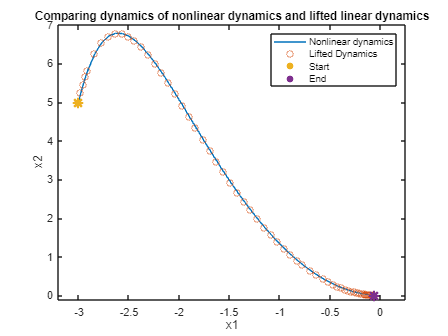

plot(x(:,1), x(:,2));
hold on
plot(y(:,1), y(:,2), 'o');
scatter(x0(1), x0(2),100, '*', 'LineWidth', 2); 
scatter(x(end,1), x(end, 2), 100, "*", 'LineWidth', 2);
title('Comparing dynamics of nonlinear dynamics and lifted linear dynamics')
xlabel('x1')
ylabel('x2')
legend('Nonlinear dynamics', 'Lifted Dynamics', 'Start', 'End')
xlim([-3.2 0.25]);
ylim([-0.1 7]);
hold off

saveas(gcf, 'all_trajectory.png');


We have confirmed that the Koopman operator preserves the behavior of the system.

## Applying Control

We will compare applying LQR to the nonlinear system by linearizing the system and for the Linear Koopman operator case. The dynamics will be modified as follows: 


$$\pmatrix{\dot{x_1} \cr \dot{x_2}} =   \pmatrix{\mu x_1 \cr \lambda(x_2-x_1^2)} + \pmatrix{ 1&0 \cr 0&1} u$$



$$\pmatrix{\dot{y_1}\cr \dot{y_2} \cr \dot{y_3}} = \pmatrix{\mu &0&0 \cr 0 & \lambda & -\lambda \cr 0 & 0 & 2\mu} \pmatrix{y_1\cr y_2\cr y_3} +  \pmatrix{1&0 \cr0&1 \cr 0&0}u$$


where u=-Kx (K = gain matrix)

#### 1) LQR on Linearized Dynamics for Nominal Nonlinear System

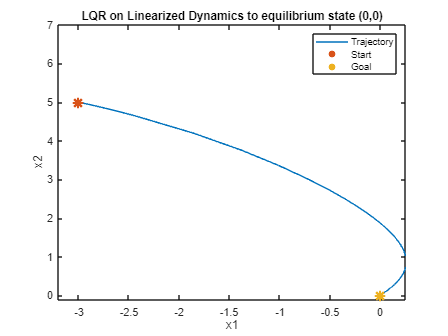

% Linearize nominal dynamics
A = [mu 0; -2*lam*x0(1) lam];
B = eye(2);
Q = eye(2);
R = 0.1*eye(2);

% Find nominal K
[K,S,P] = lqr(A, B, Q, R);

% tspan = [0,5]; 

f1_u = @(t,x)[mu*x(1)-K(1, :)*x; lam*(x(2)-x(1)^2)-K(2,:)*x];
[tl, xu] = ode45(f1_u, tspan, x0);
plot(xu(:,1), xu(:,2));
hold on
scatter(x0(1), x0(2),100, '*', 'LineWidth', 2); 
scatter(xu(end,1), xu(end, 2), 100, "*", 'LineWidth', 2);
xlim([-3.2 0.25]);
ylim([-0.1 7]);
xlabel('x1')
ylabel('x2')
title("LQR on Linearized Dynamics to equilibrium state (0,0)")
legend('Trajectory', 'Start', 'Goal')
hold off

saveas(gcf, 'lqr_traj.png');


#### 2) LQR on Linear Koopman System

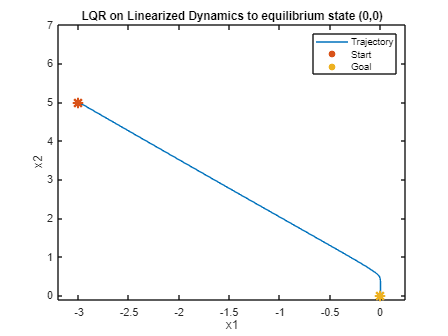

% Set values for koopman 
B_Koop = [1 0; 0 1; 0 0];
Q_Koop = [1 0 0;0 1 0;0 0 0];
R_Koop = eye(2)*0.1;

[k_koop, S_Koop, P_Koop] = lqr(A_Koop, B_Koop, Q_Koop, R_Koop);
[tk, yu] = ode45(@(t, y) (A_Koop-B_Koop*k_koop)*y, tspan, y0);
plot(yu(:,1), yu(:,2));
hold on
scatter(x0(1), x0(2),100, '*', 'LineWidth', 2); 
scatter(yu(end,1), yu(end, 2), 100, "*", 'LineWidth', 2);
xlim([-3.2 0.25]);
ylim([-0.1 7]);
xlabel('x1')
ylabel('x2')
title("LQR on Linearized Dynamics to equilibrium state (0,0)")
legend('Trajectory', 'Start', 'Goal')
hold off

saveas(gcf, 'koopman_lqr_trajectory.png');


Because we set $\mu, \lambda$ such that the system was stable to the equlibrium point (0,0), we can compare the trajectory of the uncontrolled dynamics, the controlled linearized dynamics, and controlled lifted dynamics and compare the performance of the systems.

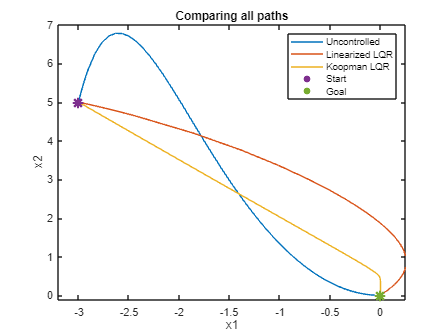

plot(x(:,1), x(:,2));
hold on
plot(xu(:,1), xu(:,2));
plot(yu(:,1), yu(:,2));
xlim([-3.2 0.25]);
ylim([-0.1 7]);
xlabel('x1')
ylabel('x2')
scatter(x0(1), x0(2),100, '*', 'LineWidth', 2); 
scatter(yu(end,1), yu(end, 2), 100, "*", 'LineWidth', 2);
title("Comparing all paths")
legend('Uncontrolled', 'Linearized LQR', 'Koopman LQR', 'Start', 'Goal')
hold off

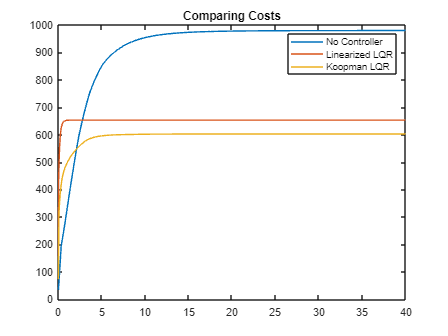

saveas(gcf, 'all_control.png');


xQx = sum((x * Q) .* x, 2);
u_linearized = -(xu *K);
xuQxu = sum((xu * Q) .* xu, 2)+sum((u_linearized*R).*u_linearized,2);
u_koop = -(yu*k_koop');
koop_xuQxu = sum((yu * Q_Koop) .* yu, 2)+sum((u_koop*R).*u_koop,2);
cost_uncontrolled = cumsum(xQx);
cost_linearized = cumsum(xuQxu);
cost_koop = cumsum(koop_xuQxu);

plot(t1, cost_uncontrolled)
hold on
plot(tl, cost_linearized)
plot(tk, cost_koop)
title("Comparing Costs");
legend("No Controller", "Linearized LQR", "Koopman LQR")
hold off

saveas(gcf, 'all_cost.png');


## Possible Directions from here:

Can we do this for a system like cart pole system?

Do we need to look at DMD/EDMD to find estimations for finding an estimate if a closed form doesn't exist?